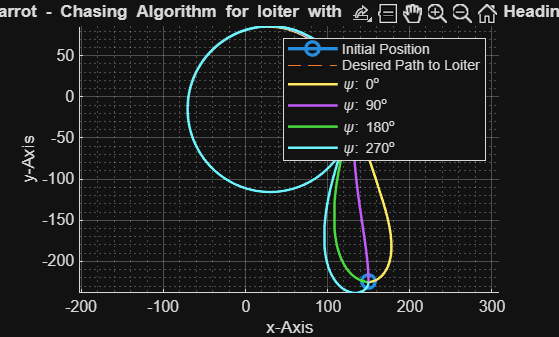

clear;
clc;
npts = 7e4;         %calculating for npts time steps
dt = 0.001;         
o = [30, -15];          %origin of cicle
r = 100;            %Circle Radius
inpos = [150, -225];   %Initial Position
lambda = 0.6;
k = 0.8;
va = 25;
Rmin = 10;          %minimum turning Radius
position = zeros([2, npts+1]);

figure;
hold on;
plot(inpos(1),inpos(2),"DisplayName","Initial Position",linewidth = 2, marker='o', markersize = 8);
legend;
axis equal;
plotCircle(o,r);


for inpsi = [0,pi/2,pi, 3*pi/2]
    psi = inpsi;
    p = inpos;
    position(:,1) = p';
    target = [0,0];

    i = 2;
    while i < npts+2
        d = sqrt((o(1) - p(1))^2 + (o(2) - p(2))^2) - r;
        theta = wrapTo2Pi(atan2((p(2) - o(2)),(p(1) - o(1))));
    
        target(1) = o(1) + r*cos(theta + lambda);
        target(2) = o(2) + r*sin(theta + lambda);
    
        psid = wrapTo2Pi(atan2((target(2) - p(2)),(target(1) - p(1))));
    
        u = k*angDiffWrap(psid, psi)*va;
        psi = wrapTo2Pi(psi + (saturate(va, Rmin, u)/va)*dt);
    
        p(1) = p(1) + va*cos(psi)*dt;
        p(2) = p(2) + va*sin(psi)*dt;
        
        position(:,i) = p';
        i = i+1;
    end
    % position = position';
    plot(position(1,:), position(2,:),"DisplayName","\psi: "+ num2str(inpsi*180/pi)+"^o", linewidth=1.5);
end
grid on;
grid minor;
legend show;
xlabel("x-Axis");
ylabel("y-Axis");
title("Carrot - Chasing Algorithm for loiter with variation in Intial Heading \psi");
hold off;


function plotCircle(o, r)
    theta = linspace(0,2*pi,1000);
    x = o(1)+r*cos(theta);
    y = o(2)+r*sin(theta);
    plot(x, y, '--', "DisplayName","Desired Path to Loiter");
end

function an = saturate(va, Rmin, u)
    max_u = va^2/Rmin;
    an = min(max(u, -max_u),max_u);
end

function diff = angDiffWrap(psid, psi)
    if (psi > 3*pi/2 && psi < 2*pi) && (psid > 0 && psid < pi/2)
       diff =  (psid+2*pi) - psi;
    elseif  (psid > 3*pi/2 && psid < 2*pi) && (psi > 0 && psi < pi/2)
        diff = psid - (psi +2*pi);
    else
        diff = psid - psi;
    end
end
